% skutecznosc mvp graczy w grach
clearvars
dane=readtable('player_mvp_stats.csv');

rozegrane_gry=dane(:,10);
rozegrane_gry=table2array(rozegrane_gry);
% usuwamy tych graczy, którzy nie podali swoich danych
rozegrane_gry=rmmissing(rozegrane_gry);

% obliczenia klasycznie dla średniej


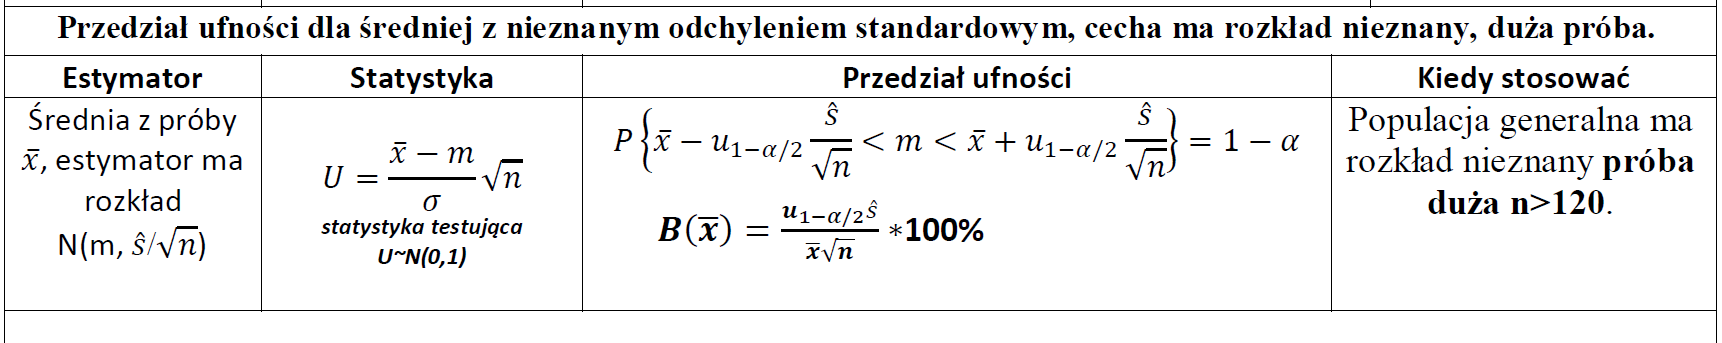

alfa=0.01;
n=length(rozegrane_gry)

n = 14042

srednia=mean(rozegrane_gry)

srednia = 0.4385

odchylenie_standardowe=std(rozegrane_gry)

odchylenie_standardowe = 0.0926

kwantyl=icdf('normal', (1-alfa/2), 0, 1)

kwantyl = 2.5758

przedzial_ufnosci=[srednia-kwantyl*odchylenie_standardowe/sqrt(n), srednia+kwantyl*(odchylenie_standardowe/sqrt(n))]

przedzial_ufnosci =     0.4365    0.4406


% precyzja szacowania
B=(kwantyl*odchylenie_standardowe)/(srednia*sqrt(n))*100

B = 0.4592

B<5% -> duża precyzja szacowania

# **Dla poziomu  ufności 1-alfa=0.99   przedział  ufności dla średniej "skuteczność graczy mvp w grach" wynosi  0.4365<srednia< 0.4406  Względna precyzja  0.4592 (duża precyzja)**

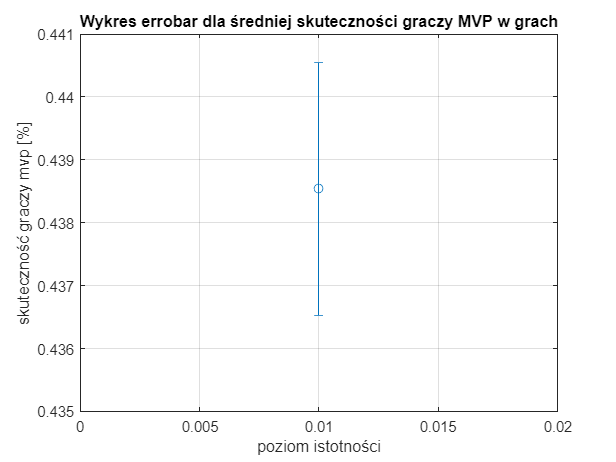

% errorbar dla sredniej
x=0.01;
y=srednia;
figure
% errorbar dla średniej i przedział ufności 1-alfa=0.95
errorbar(x,y,srednia-przedzial_ufnosci(1), przedzial_ufnosci(2)-srednia,'o')
grid on
ylim([0.435, 0.4410])
xlim([0 0.02])
title('Wykres errobar dla średniej skuteczności graczy MVP w grach')
xlabel('poziom istotności')
ylabel('skuteczność graczy mvp [%]')

% estymacja punktowa
% blad standardowy sredniej
D=odchylenie_standardowe/sqrt(n)

D = 7.8181e-04

% blad wzgledny
V=(D/srednia)*100

V = 0.1783

V<7.5% wysoce precyzyjna estymacja

function H=chi2test(x, alpha)
%   CHI2TEST: Single sample Pearson Chi Square goodness-of-fit hypothesis test.
%   H=CHI2TEST(X,ALPHA) performs the particular case of Pearson Chi Square
%   test to determine whether the null hypothesis of composite normality PDF is 
%   a reasonable assumption regarding the population distribution of a random sample X
%   with the desired significance level ALPHA.
%
%   H indicates the result of the hypothesis test according to the MATLAB rules 
%   of conditional statements:
%   H=1 => Do not reject the null hypothesis at significance level ALPHA.
%   H=0 => Reject the null hypothesis at significance level ALPHA.
% 
%   The Chi Square hypotheses and test statistic in this particular case are:
% 
%   Null Hypothesis:        X is normal with unknown mean and variance.
%   Alternative Hypothesis: X is not normal.
%
%   The random sample X is shifted by its estimated mean and normalized by its
%   estimated standard deviation. The tested bins XP of the assumed normal distribution
%   are chosen [-inf, -1.6:0.4:1.6, inf] to avoid unsufficient statistics. 
%   
%   Let E(x) be the expected frequency X falls within XP according to the normal
%   distribution and O(x) be the observed frequency. The Pearson statistic, 
%   X2=SUM((E(x)-O(x))^2/E(x)) distributes Chi Square with length(XP)-3 degrees
%   of freedom. 
%
%   The decision to reject the null hypothesis is taken when the P value (probability that Chi2
%   random value with length(XP)-3 degrees of freedomd is greater than X2) is less than 
%   significance level ALPHA. 
%
%   X must be a row vector representing a random sample. ALPHA must be a scalar.
%   The function doesn't check the formats of X and ALPHA, as well as a number of the
%   input and output parameters.
%
%   The asymptotic limit of the Chi Square test presented is reached when LENGTH(X)>90.
%
% Acknowledge: Dr. S. Loyka
%
% Author: G. Levin, May, 2003.
%
% References:
%   W. T. Eadie, D. Drijard, F. E. James, M Roos and B. Sadoulet, "Statistical Methods
%   in Experimental Physics", North-Holland, Sec. Reprint, 1982.

%Normalize x
N=length(x);
x=(x-mean(x))/std(x); %standardization

xp=[-inf, -1.6:.4:1.6, inf]; %tested bins
E=0.5*N*diff(erfc(-xp/sqrt(2))); %expected frequency
S=histc(x, xp); 
O=S(1:end-1); %%observed frequency
%plot(xp(2:end),E,'k-',xp(2:end),O,'k.');
x2=sum((E-O).^2./E); %statistics

pval=1-gammainc(x2/2,(length(O)-3)/2); %p value

H=(pval>=alpha);
end